# Shift to Centered Spectrum

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

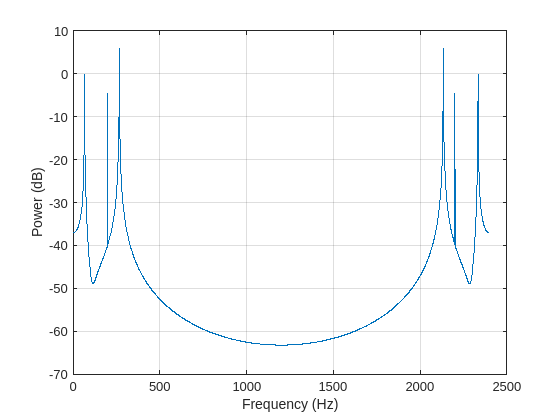

load ./data/psdsig.mat
Y = fft(sig) ;
f = (0:n-1)*(fs/n);
n = length(sig);
p = abs(Y).^2;
plot(f, 10*log10(p))
grid on
xlabel("Frequency (Hz)")
ylabel("Power (dB)")

## Task 1

You can shift the zero-frequency component to center of spectrum to make a centered spectrum.

You can change the frequencies from two-sided to centered using the `fftshift` function.

pshift = fftshift(p)

pshift =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


## Task 2

You also need to shift your frequency values to match. For even FFT sizes, you can subtract `fs/2` from your frequency values.

fshift = f-fs/2

fshift =        -1200       -1199       -1198       -1197       -1196       -1195       -1194       -1193       -1192       -1191       -1190       -1189       -1188       -1187       -1186       -1185       -1184       -1183       -1182       -1181       -1180       -1179       -1178       -1177       -1176       -1175       -1174       -1173       -1172       -1171       -1170       -1169       -1168       -1167       -1166       -1165       -1164       -1163       -1162       -1161       -1160       -1159       -1158       -1157       -1156       -1155       -1154       -1153       -1152       -1151


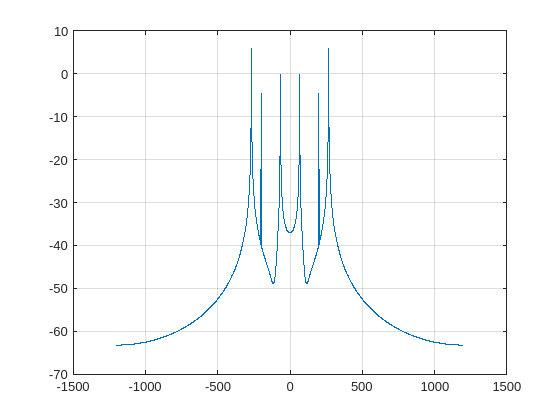

plot(fshift, 10*log10(pshift))
grid on

## Task 3

For real-valued signals, the power spectrum is symmetric around zero, so you only need to plot the one-sided spectrum.

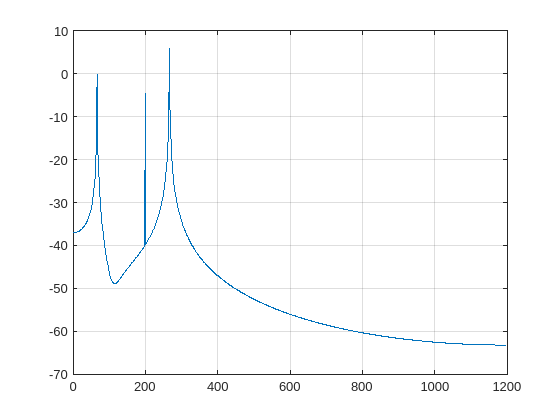

fhalf = f(1:n/2);
phalf = p(1:n/2);
plot(fhalf, 10*log10(phalf))
grid on